
% open train image folder
traindir="/home/dmplus/2019_juniorI/CV/assignment/assignment1/dataset/AR/AR_Train_image";

if ~isfolder(traindir)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', traindir);
  uiwait(warndlg(errorMessage));
  return;
end

trainpattern=fullfile(traindir,'*.bmp');
trainimg=dir(trainpattern);
numoftrain=length(trainimg);

% read images + 2d -> 1d +  img vector concatenate to image matrix
imgmtx=[];

for i=1:numoftrain
    curfname=fullfile(traindir,trainimg(i).name);
    img=imread(curfname);
    grayscaleimg=rgb2gray(img);
    grayscaleimg=im2double(grayscaleimg);
    imgvec=grayscaleimg(:);
    imgmtx=[imgmtx,imgvec];
end

% find mean face
meanface=mean(imgmtx,2);

% value minus mean face
imgmtx=imgmtx-meanface;

% calculate covariance matrix
covmtx=cov(imgmtx');

gpuDevice

ans =   CUDADevice with properties:

                      Name: 'GeForce GTX 1060 6GB'
                     Index: 1
         ComputeCapability: '6.1'
            SupportsDouble: 1
             DriverVersion: 10.1000
            ToolkitVersion: 10.1000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 6.3703e+09
           AvailableMemory: 2.0703e+09
       MultiprocessorCount: 10
              ClockRateKHz: 1784500
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 1
          CanMapHostMemory: 1
           DeviceSupported: 1
            DeviceSelected: 1


% find eigenvalues and eigenvector
% gpucovmtx=gpuArray(covmtx);
[eigvec,eigvals,eigvec2]=svds(covmtx,9,"largest")

eigvec =    -0.0038   -0.0001   -0.0001   -0.0005    0.0068   -0.0048    0.0003    0.0023   -0.0022
   -0.0038   -0.0004   -0.0003   -0.0004    0.0067   -0.0036   -0.0001    0.0016   -0.0015
   -0.0037   -0.0009   -0.0003   -0.0001    0.0063   -0.0022   -0.0002    0.0006   -0.0008
   -0.0035   -0.0012   -0.0003    0.0001    0.0060   -0.0014   -0.0001    0.0000    0.0001
   -0.0035   -0.0013   -0.0005    0.0002    0.0055   -0.0009    0.0005   -0.0003    0.0006
   -0.0033   -0.0013   -0.0007    0.0004    0.0052   -0.0000    0.0007   -0.0011    0.0011
   -0.0032   -0.0014   -0.0008    0.0005    0.0047    0.0009    0.0009   -0.0015    0.0019
   -0.0031   -0.0015   -0.0009    0.0006    0.0043    0.0013    0.0011   -0.0017    0.0030
   -0.0031   -0.0017   -0.0011    0.0007    0.0042    0.0018    0.0014   -0.0020    0.0033
   -0.0031   -0.0017   -0.0012    0.0007    0.0041    0.0022    0.0016   -0.0023    0.0037


eigvals =   350.5943         0         0         0         0         0         0         0         0
         0  168.1286         0         0         0         0         0         0         0
         0         0  134.5771         0         0         0         0         0         0
         0         0         0   90.7503         0         0         0         0         0
         0         0         0         0   55.7670         0         0         0         0
         0         0         0         0         0   19.5747         0         0         0
         0         0         0         0         0         0   17.6757         0         0
         0         0         0         0         0         0         0   13.3162         0
         0         0         0         0         0         0         0         0   11.9396


eigvec2 =    -0.0038   -0.0001   -0.0001   -0.0005    0.0068   -0.0048    0.0003    0.0023   -0.0022
   -0.0038   -0.0004   -0.0003   -0.0004    0.0067   -0.0036   -0.0001    0.0016   -0.0015
   -0.0037   -0.0009   -0.0003   -0.0001    0.0063   -0.0022   -0.0002    0.0006   -0.0008
   -0.0035   -0.0012   -0.0003    0.0001    0.0060   -0.0014   -0.0001    0.0000    0.0001
   -0.0035   -0.0013   -0.0005    0.0002    0.0055   -0.0009    0.0005   -0.0003    0.0006
   -0.0033   -0.0013   -0.0007    0.0004    0.0052   -0.0000    0.0007   -0.0011    0.0011
   -0.0032   -0.0014   -0.0008    0.0005    0.0047    0.0009    0.0009   -0.0015    0.0019
   -0.0031   -0.0015   -0.0009    0.0006    0.0043    0.0013    0.0011   -0.0017    0.0030
   -0.0031   -0.0017   -0.0011    0.0007    0.0042    0.0018    0.0014   -0.0020    0.0033
   -0.0031   -0.0017   -0.0012    0.0007    0.0041    0.0022    0.0016   -0.0023    0.0037


% reshape the vector back to image size
vectors=num2cell(eigvec,1);

matrices={};

for i=1:9
    matrices{end+1}=reshape(vectors{i},165,120);
end

pathname = 'eigfaces/'

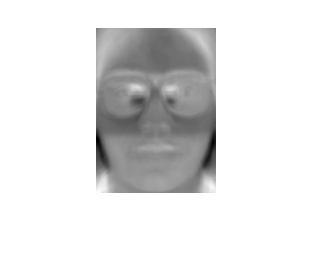

% convert matrix back to grayscale image
pathname='eigfaces/'


for i=1:9
    eigface=mat2gray(matrices{i});
    imshow(eigface);
    if(i==1 || i==5 || i==9)
        fname=strcat('d',num2str(i));
       imwrite(eigface,fullfile('eigfaces/',strcat(fname,'.bmp'))); 
    end
end

% save the eigenface and mean face to csv file
eigfacemtx=[];

for i=1:9
    grayvec=mat2gray(matrices{i});
    grayvec=grayvec(:);
    eigfacemtx=[eigfacemtx,grayvec];
end

Undefined variable matrices.


csvwrite('eigenface.csv',eigfacemtx);


csvwrite('original_mean.csv',meanface);